clear;
clc;

#### 一、用MATLAB语言描述下列系统，并求出零极点。

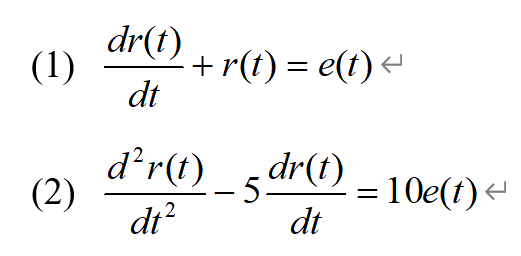

%%%%%%(1)%%%%%%
%求极零点
A1=[0 1];
B1=[1 1];
sys1=tf(A1,B1);
[z1,p1,k1]=tf2zp(A1,B1);
fprintf("z=");disp(z1);%空

z=

fprintf("p=");disp(p1);

p=    -1



fprintf("k=");disp(k1);

k=     1



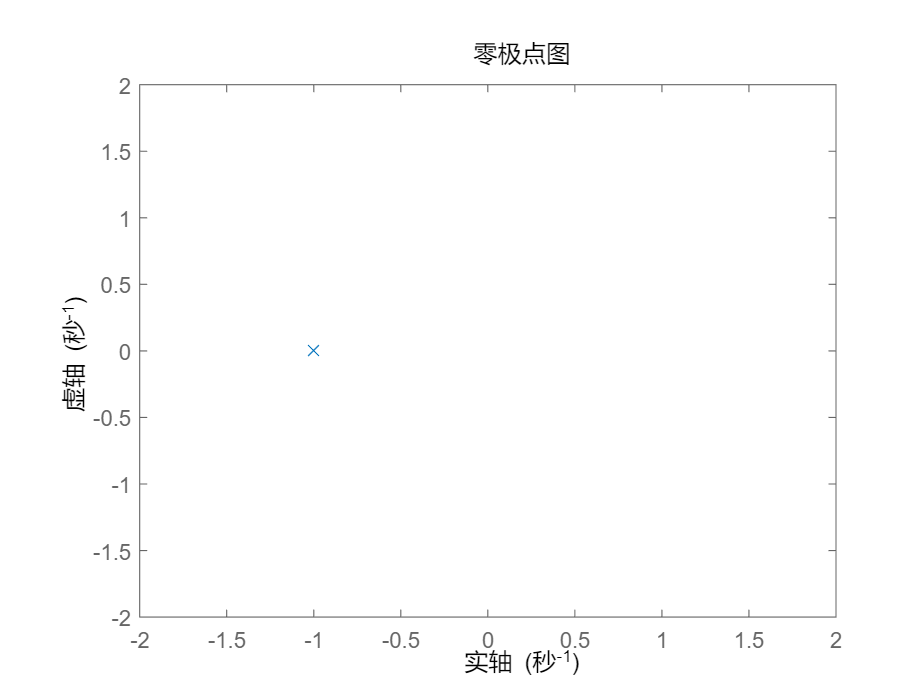

%作极零图
figure(1);
pzmap(sys1);
axis([-2,2,-2,2]);


%%%%%%(2)%%%%%%
%求极零点
A2=[0 0 10];
B2=[1 -5 0];
sys2=tf(A2,B2);
[z2,p2,k2]=tf2zp(A2,B2);
disp('z=');disp(z2);%空

z=


disp('p=');disp(p2);

p=
     0
     5



fprintf("k=");disp(k2);

k=    10



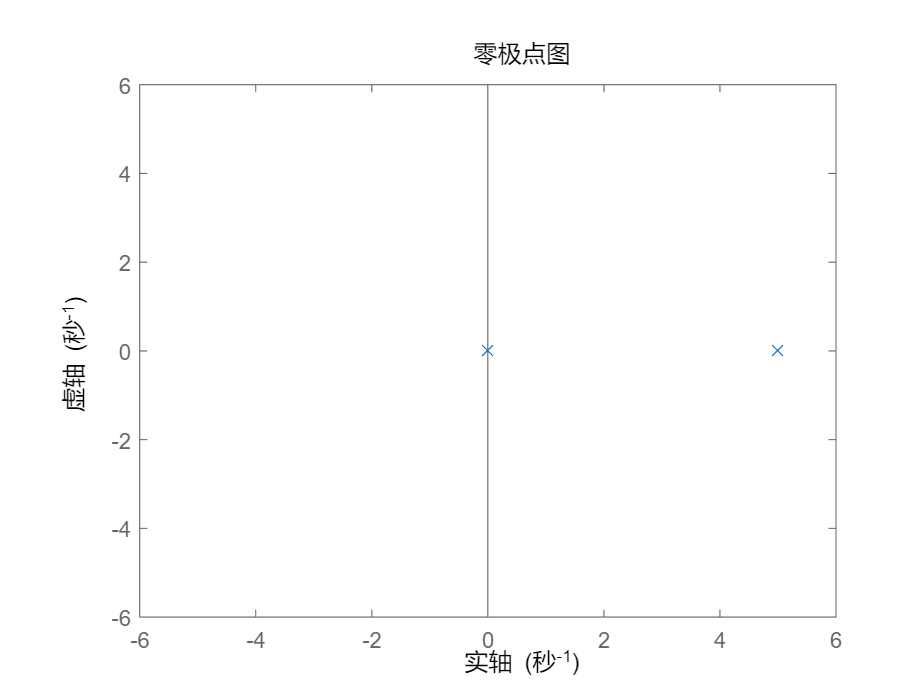

%作极零图
figure(2);
pzmap(sys2);
axis([-6,6,-6,6]);

clear;
clc;

#### 二、已知下列传递函数H(s)或者H(z)，求其零极点，并画出零极点图。

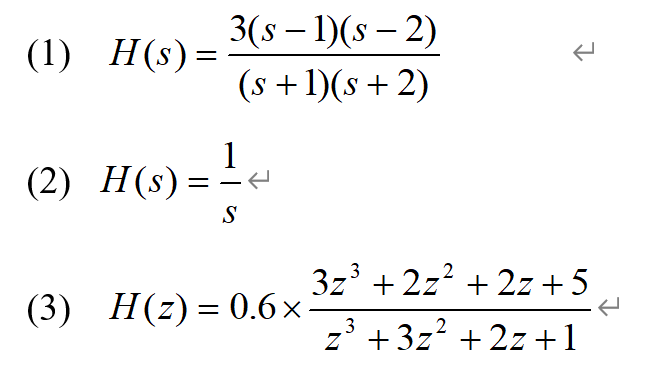

%%%%%%(1)%%%%%%
%求极零点
A1=3*conv([1 -1],[1 -2]);
B1=conv([1 1],[1 2]);
[z1,p1,k1]=tf2zp(A1,B1)

z1 =      2
     1


p1 =     -2
    -1


k1 = 3

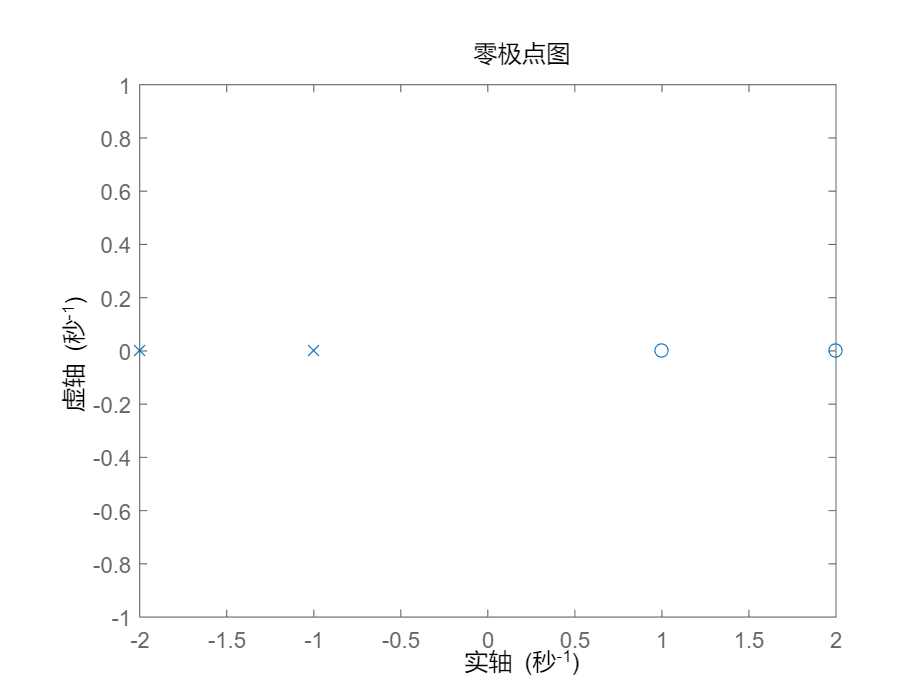

sys1=tf(A1,B1);
%作极零图
figure(3);
pzmap(sys1);


%%%%%%(2)%%%%%%
%求极零点
A2=[1];
B2=[1 0];
[z2,p2,k2]=tf2zp(A2,B2)


z2 =

  空的 0×1 double 列向量



p2 = 0

k2 = 1

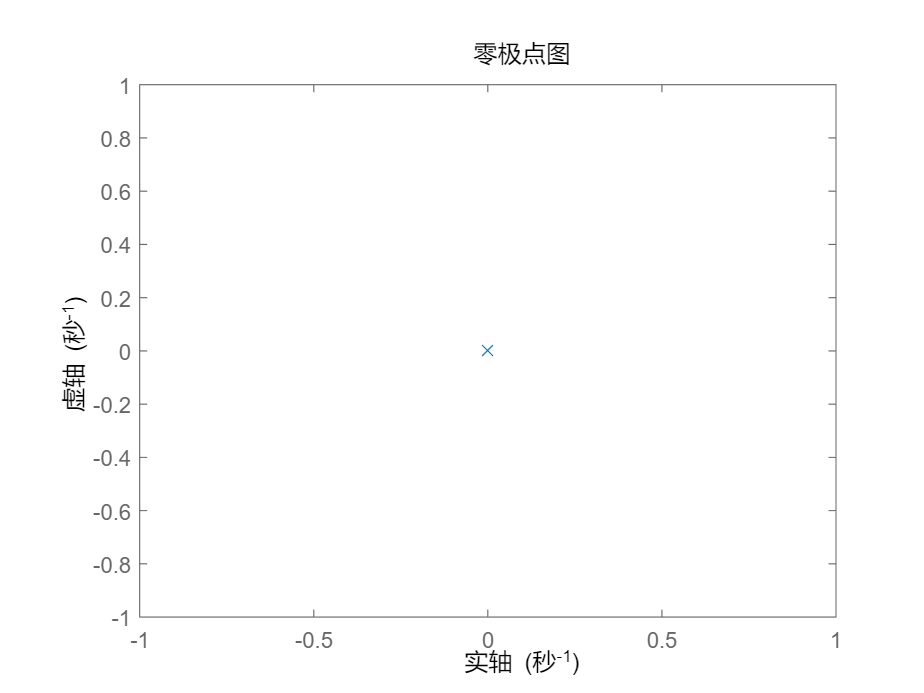

sys2=tf(A2,B2);
%作极零图
figure(4);
pzmap(sys2);


%%%%%%(3)%%%%%%
%求极零点
A3=0.6*[3 2 2 5];
B3=[1 3 2 1];
[z3,p3,k3]=tf2zpk(A3,B3)

z3 =   -1.2284 + 0.0000i
   0.2809 + 1.1304i
   0.2809 - 1.1304i


p3 =   -2.3247 + 0.0000i
  -0.3376 + 0.5623i
  -0.3376 - 0.5623i


k3 = 1.8000

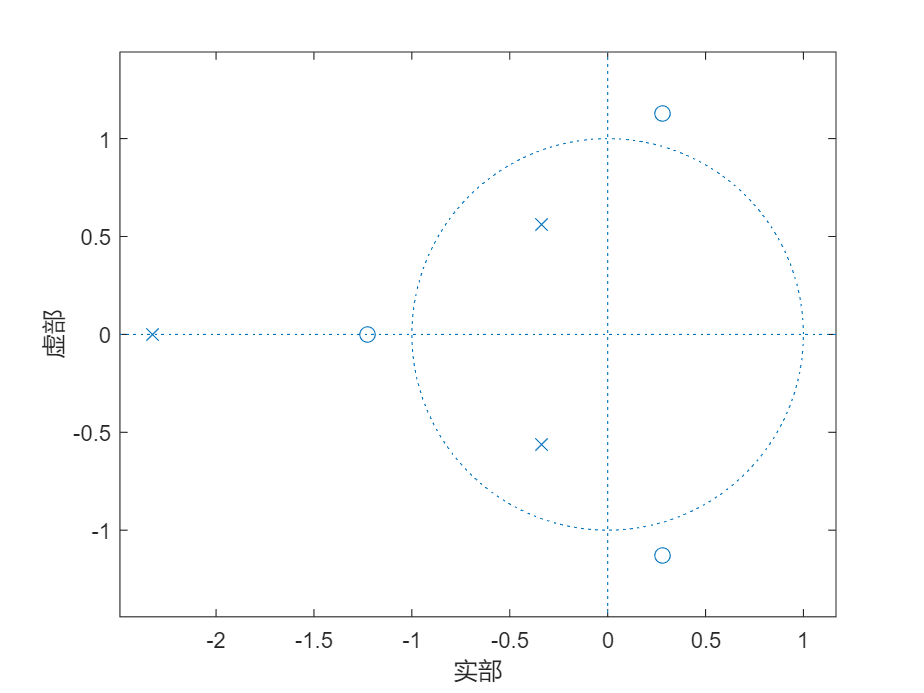

sys3=tf(A3,B3);
%作极零图
figure(5);
zplane(z3,p3);

clear;
clc;

#### 三、求出下列系统的零极点，判断系统的稳定性。

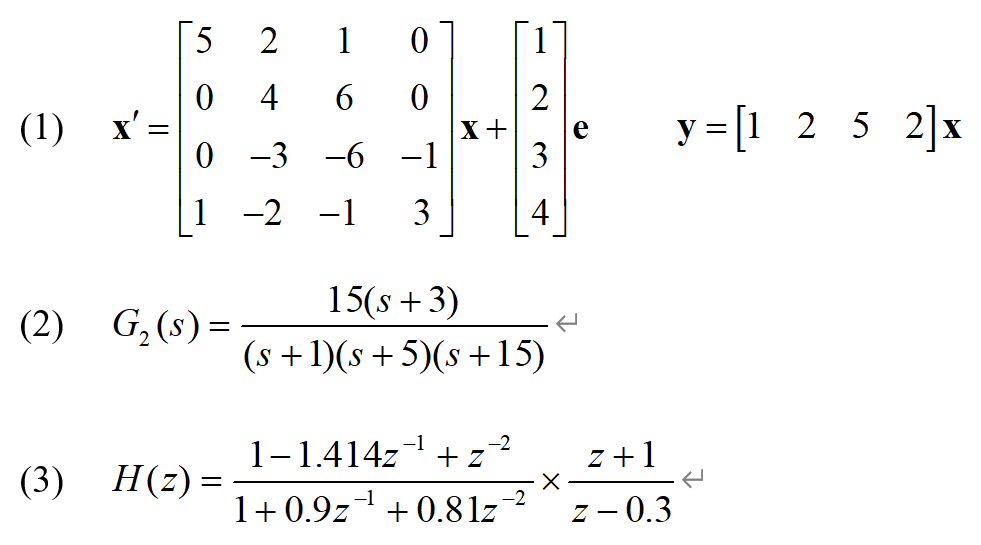

%%%%%%(1)%%%%%%
%求极零点
a1=[5 2 1 0;0 4 6 0;0 -3 -6 -1;1 -2 -1 3];
b1=[1 2 3 4].';
c1=[1 2 5 2];
d1=[0];
sys1=ss(a1,b1,c1,d1);
[z1,p1,k1]=ss2zp(a1,b1,c1,d1)

z1 =    4.0280 + 1.2231i
   4.0280 - 1.2231i
   0.2298 + 0.0000i


p1 =   -3.4949 + 0.0000i
   4.4438 + 0.1975i
   4.4438 - 0.1975i
   0.6074 + 0.0000i


k1 = 28

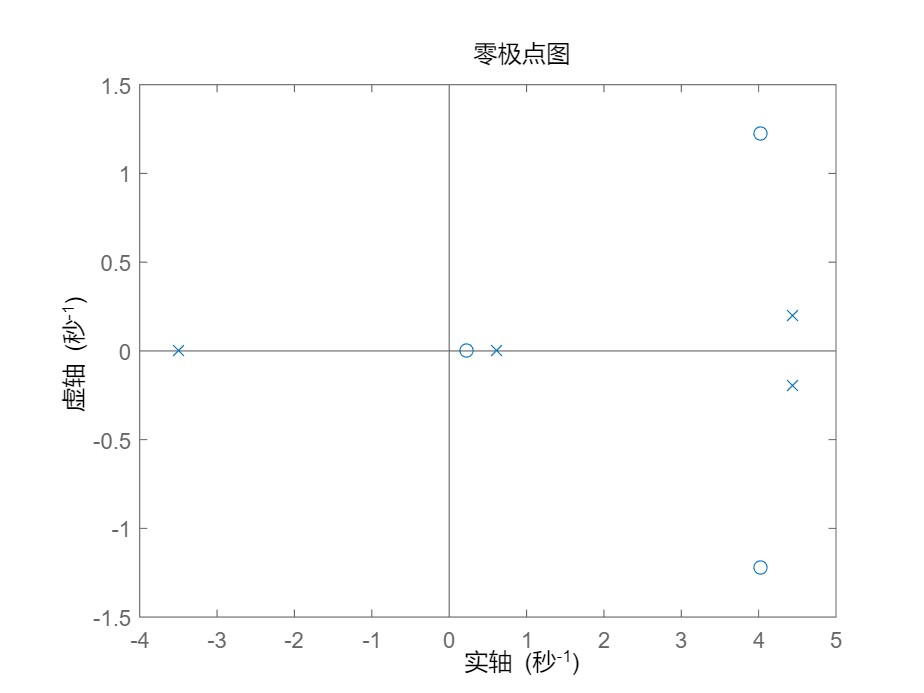

%作极零图
figure(6);
pzmap(sys1);

分析稳定性：由极零图可知，有三个极点在虚轴右侧，所以该系统不稳定。

%%%%%%(2)%%%%%%
%求极零点
A2=15*[1 3];
B2=conv([1 15],conv([1 1],[1 5]));
sys2=tf(A2,B2);
[z2,p2,k2]=tf2zp(A2,B2)

z2 = -3

p2 =   -15.0000
   -5.0000
   -1.0000


k2 = 15

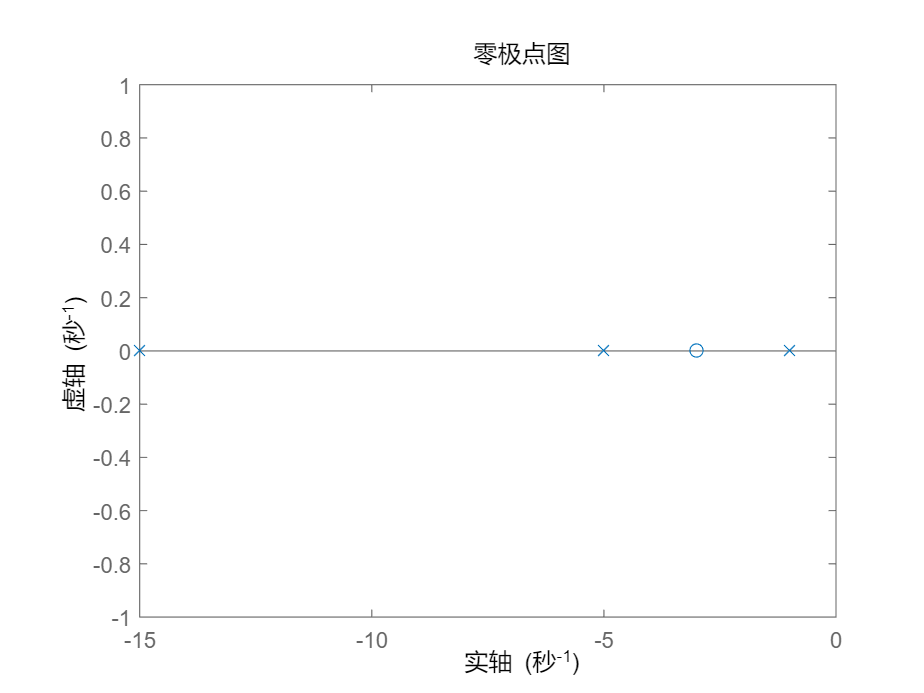

%作极零图
figure(7);
pzmap(sys2);

稳定性分析：由极零图可知，极点都在虚轴左侧，所以系统是稳定的。

%%%%%%(3)%%%%%%
%求极零点
A3=conv([1 -1.414 1],[1 1]);
B3=conv([1 0.9 0.81],[1 -0.3]);
sys3=tf(A3,B3,-1);
[z3,p3,k3]=tf2zpk(A3,B3)

z3 =   -1.0000 + 0.0000i
   0.7070 + 0.7072i
   0.7070 - 0.7072i


p3 =   -0.4500 + 0.7794i
  -0.4500 - 0.7794i
   0.3000 + 0.0000i


k3 = 1

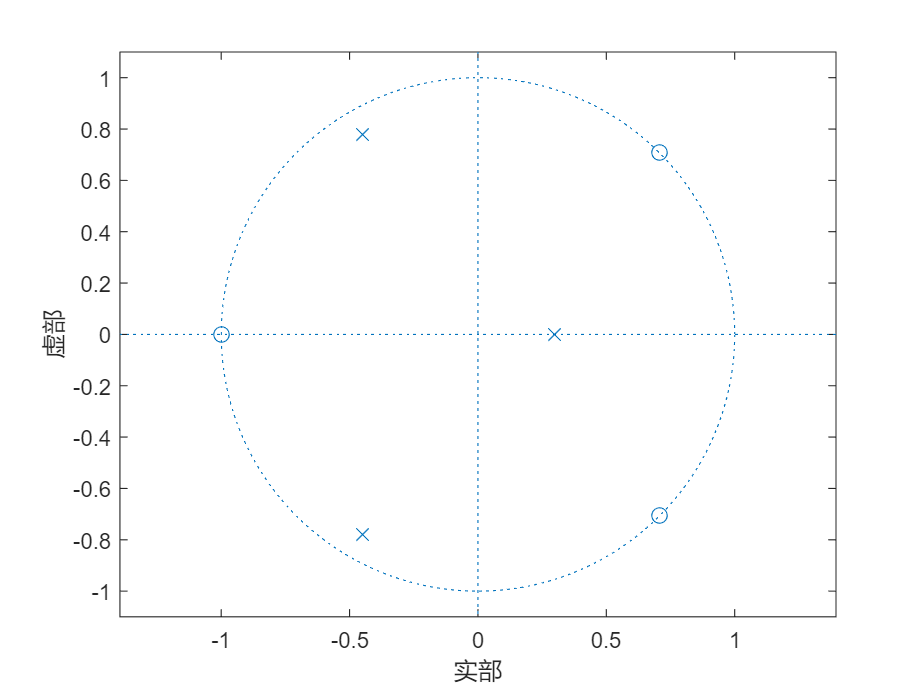

%作极零图
figure(8);
zplane(z3,p3);

稳定性分析：由极零图可知，极点全分布于单位圆内，所以系统是稳定的`。`

clear;
clc;

#### 四、系统特征方程如下，试写一段程序，利用R-H准则判别系统稳定。

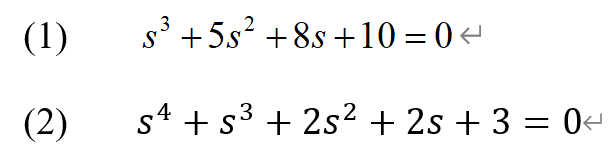

%%%%%%(1)%%%%%%
q1=[1 5 8 10];
n1=length(q1);
R1=zeros(4,4);
R1(1,1)=q1(1);R1(2,1)=q1(2);R1(1,2)=q1(3);R1(2,2)=q1(4);
for i=3:n1
    for j=1:n1-1
        R1(i,j)=(R1(i-1,1)*R1(i-2,j+1)-R1(i-2,1)*R1(i-1,j+1))/R1(i-1,1);
    end
end
disp(R1);

     1     8     0     0
     5    10     0     0
     6     0     0     0
    10     0     0     0



稳定性分析：罗斯-霍维斯数列的第一列全为正数，故系统稳定。

%%%%%%(2)%%%%%%
q2=[1 1 2 2 3];
R2=zeros(5,5);
n2=length(q2);
R2(1,1)=q2(1);R2(2,1)=q2(2);R2(1,2)=q2(3);R2(2,2)=q2(4);R2(2,2)=q2(4);R2(1,3)=q2(5);
for i=3:n2
    for j=1:n2-1
        R2(i,j)=(R2(i-1,1)*R2(i-2,j+1)-R2(i-2,1)*R2(i-1,j+1))/R2(i-1,1);
    end
end
disp(R2);

     1     2     3     0     0
     1     2     0     0     0
     0     3     0     0     0
  -Inf   NaN   NaN   NaN     0
   NaN   NaN   NaN   NaN     0



由于矩阵第三行的首个元素出现了0，会影响接下来的判断，故而采用乘以(s+1)策略来判断。

q21=[1 1 2 2 3];
q22=[1 1];
q2=conv(q21,q22);
n2=length(q2);
R2=zeros(6,6);
R2(1,1)=q2(1);R2(2,1)=q2(2);R2(1,2)=q2(3);R2(2,2)=q2(4);R2(2,2)=q2(4);R2(1,3)=q2(5);R2(2,3)=q2(6);
for i=3:n2
    for j=1:n2-1
        R2(i,j)=(R2(i-1,1)*R2(i-2,j+1)-R2(i-2,1)*R2(i-1,j+1))/R2(i-1,1);
    end
end
disp(R2);

    1.0000    3.0000    5.0000         0         0         0
    2.0000    4.0000    3.0000         0         0         0
    1.0000    3.5000         0         0         0         0
   -3.0000    3.0000         0         0         0         0
    4.5000         0         0         0         0         0
    3.0000         0         0         0         0         0



稳定性分析：罗斯-霍维斯数列的第一列有正数也有负数，故系统不稳定。